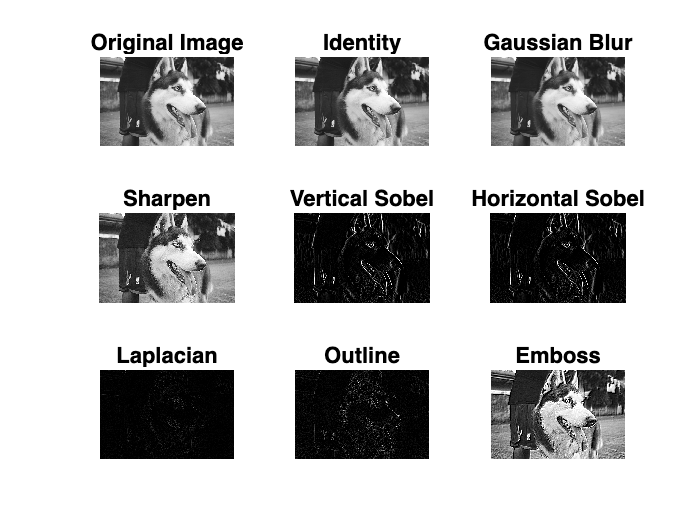

%Initialize all kernels from manual
Iden = [0 0 0;...
        0 1 0;...
        0 0 0];
Gblur = (1/16)*...
        [1 2 1;...
        2 4 2;...
        1 2 1];
Sharp = [0 -1 0;...
        -1 5 -1;...
        0 -1 0];
VertSob = [1 0 -1;...
           2 0 -2;...
           1 0 -1];
HorSob = [1 0 -1;...
           2 0 -2;...
           1 0 -1];
Lap = [0 1 0;...
        1 -4 1;...
        0 1 0];
Outl = [-1 -1 -1;...
        -1 8 -1;...
        -1 -1 -1];
Embo = [-2 -1 0;...
        -1 1 1;...
        0 1 2];
%Acquire image and place on your current directory
%read the image using imread() and store it into a variable
I = imread('dog', 'png');
%Convert image to greyscale
Igs = rgb2gray(I);

%Filter image with all convolution kernels. 
%Use function imfilter()
%Assure 512x512 image using uint8()
Idenfilconv = uint8(conv2(Igs, Iden, 'same'));
Idenfil = uint8(imfilter(Igs, Iden));
Igbfil = uint8(imfilter(Igs, Gblur));
Ishfil = uint8(imfilter(Igs, Sharp));
Ivsfil = uint8(imfilter(Igs, VertSob));
Ihsfil = uint8(imfilter(Igs, HorSob));
Ilapfil = uint8(imfilter(Igs, Lap));
Ioutlfil = uint8(imfilter(Igs, Outl));
Iembofil = uint8(imfilter(Igs, Embo));

%Show all the filtered images in one figure
figure(1);
subplot(331); imshow(Igs); title('Original Image')
subplot(332); imshow(Idenfil); title('Identity')
subplot(333); imshow(Igbfil); title('Gaussian Blur')
subplot(334); imshow(Ishfil); title('Sharpen')
subplot(335); imshow(Ivsfil); title('Vertical Sobel')
subplot(336); imshow(Ihsfil); title('Horizontal Sobel')
subplot(337); imshow(Ilapfil); title('Laplacian')
subplot(338); imshow(Ioutlfil); title('Outline')
subplot(339); imshow(Iembofil); title('Emboss')

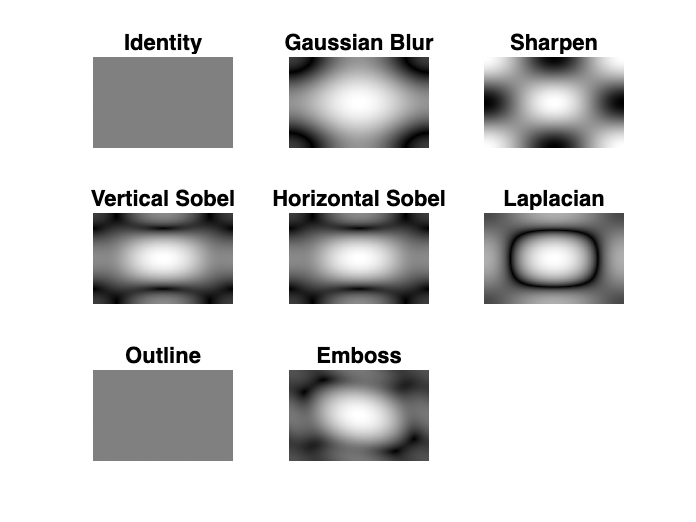

%Plot the 2D Magnitude Spectrum of All Filters
%Initialize a function to calculate and plot the 2D magnitude spectrum
figure(2);
subplot(331); imgmagspec2D(Iden); title('Identity')
subplot(332); imgmagspec2D(Gblur); title('Gaussian Blur')
subplot(333); imgmagspec2D(Sharp); title('Sharpen')
subplot(334); imgmagspec2D(VertSob); title('Vertical Sobel')
subplot(335); imgmagspec2D(HorSob); title('Horizontal Sobel')
subplot(336); imgmagspec2D(Lap); title('Laplacian')
subplot(337);imgmagspec2D(Outl); title('Outline')
subplot(338); imgmagspec2D(Embo); title('Emboss')

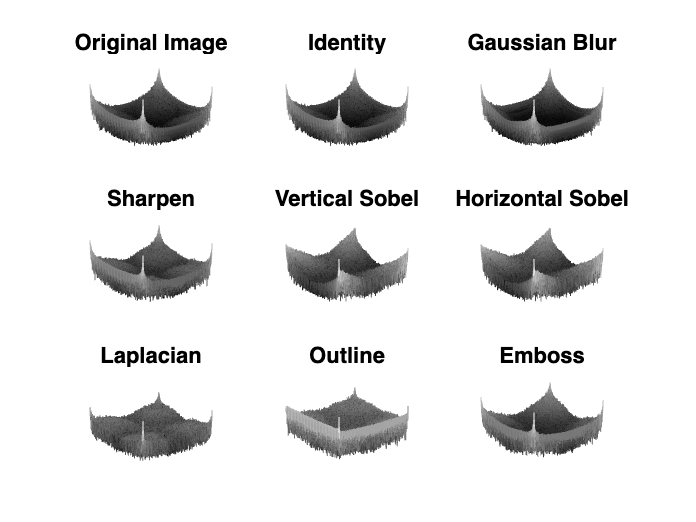

%Plot the 3D Magnitude Spectrum of All Filters
%Initialize a function to calculate and plot the 3D magnitude spectrum
figure(3);
subplot(331); imgmagspec3D(Iden); title('Identity')
subplot(332); imgmagspec3D(Gblur); title('Gaussian Blur')
subplot(333); imgmagspec3D(Sharp); title('Sharpen')
subplot(334); imgmagspec3D(VertSob); title('Vertical Sobel')
subplot(335); imgmagspec3D(HorSob); title('Horizontal Sobel')
subplot(336); imgmagspec3D(Lap); title('Laplacian')
subplot(337);imgmagspec3D(Outl); title('Outline')
subplot(338); imgmagspec3D(Embo); title('Emboss')
%Plot the 2D Magnitude Spectrum of Filtered Images
figure(4);
subplot(331); imgmagspec2D(Igs); title('Original Image')
subplot(332); imgmagspec2D(Idenfil); title('Identity')
subplot(333); imgmagspec2D(Igbfil); title('Gaussian Blur')
subplot(334); imgmagspec2D(Ishfil); title('Sharpen')
subplot(335); imgmagspec2D(Ivsfil); title('Vertical Sobel')
subplot(336); imgmagspec2D(Ihsfil); title('Horizontal Sobel')
subplot(337); imgmagspec2D(Ilapfil); title('Laplacian')
subplot(338); imgmagspec2D(Ioutlfil); title('Outline')
subplot(339); imgmagspec2D(Iembofil); title('Emboss')
%Plot the 3D Magnitude Spectrum of Filtered Images
figure(5);
subplot(331); imgmagspec3D(Igs); title('Original Image')
subplot(332); imgmagspec3D(Idenfil); title('Identity')
subplot(333); imgmagspec3D(Igbfil); title('Gaussian Blur')
subplot(334); imgmagspec3D(Ishfil); title('Sharpen')
subplot(335); imgmagspec3D(Ivsfil); title('Vertical Sobel')
subplot(336); imgmagspec3D(Ihsfil); title('Horizontal Sobel')
subplot(337); imgmagspec3D(Ilapfil); title('Laplacian')
subplot(338); imgmagspec3D(Ioutlfil); title('Outline')
subplot(339); imgmagspec3D(Iembofil); title('Emboss')

function imgmagspec2D(img) %image must be a convolution kernel or a grayscale image
F = fftshift(fft2(double(mat2gray(img)), 512, 512));
Ilog = log(1+abs(F));
colormap(gray); imagesc(Ilog); axis off
end
function imgmagspec3D(img)
H=fftshift(fft2(double(mat2gray(img)), 512, 512));
Hlog=log(1+abs(H));
u=-256:255;
v=-256:255;
[u,v]=meshgrid(u,v);
mesh(u,v,[Hlog(257:512,257:512),Hlog(257:512,1:256);
Hlog(1:256,257:512) Hlog(1:256,1:256)]); axis off
end